% Partition coefficients of antimicrobial peptides by fluroescence
% measurement

clc,clear
syms w t

L1=[0;1;3;5;7;9;11;13;15;20] 

L1 =      0
     1
     3
     5
     7
     9
    11
    13
    15
    20


% Peptides concentration normally as μM
F1=[1;1.017946162;1.064805583;1.121635095;1.28115653;1.307577268;
    1.479062812;1.51894317;1.558325025;1.610667996];
% F/F0 values at different peptides' concentration
f1=fittype(['1+c-c*(1/(1+a*w))'],'independent','w','coefficients',{'a','c'});
% Two-parameter function fitting
cfun=fit(L1,F1,f1)

cfun =      General model:
     cfun(w) = 1+c-c*(1/(1+a*w))
     Coefficients (with 95% confidence bounds):
       a =     0.01423  (-0.01794, 0.0464)
       c =       3.003  (-2.655, 8.661)

Li=0:0.1:20;
Fi=cfun(Li);

L2=[0;1;3;5;7;9;11;13;15;20]

L2 =      0
     1
     3
     5
     7
     9
    11
    13
    15
    20


F2=[1;1.040585182;1.019348749;1.19726286;1.294006607;1.560169891;1.599339311;1.637564889;1.780084946;1.925908447];
f2=fittype(['1+d-d*(1/(1+b*t))'],'independent','t','coefficients',{'b','d'});
cfun=fit(L2,F2,f2)

cfun =      General model:
     cfun(t) = 1+d-d*(1/(1+b*t))
     Coefficients (with 95% confidence bounds):
       b =    0.003695  (-0.02128, 0.02867)
       d =       14.08  (-76.21, 104.4)

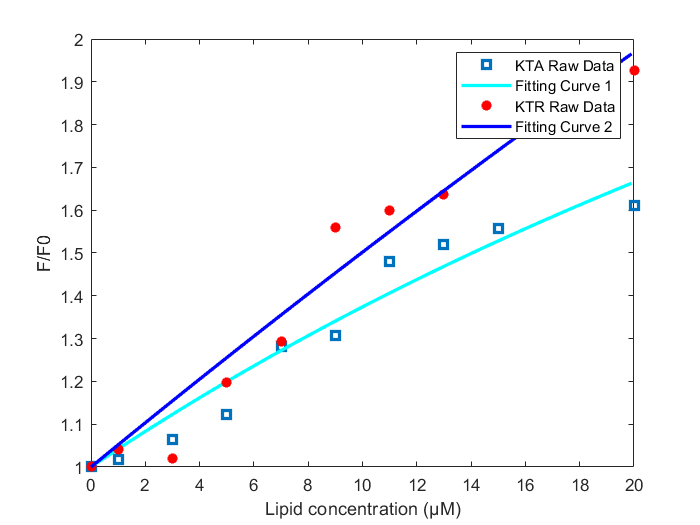

Lii=0:0.1:20;
Fii=cfun(Lii);

plot(L1,F1,'s',Li,Fi,'c-','LineWidth',2) %KTA
hold on
plot(L2,F2,'r*',Lii,Fii,'b-','LineWidth',2) %KTR
hold on
xlabel 'Lipid concentration (μM)'
ylabel 'F/F0'
legend('KTA Raw Data','Fitting Curve 1','KTR Raw Data','Fitting Curve 2','Leg2 Raw Data',' Fitting Curve 3')